clear
close all
% %%load file
% %load('/Users/platel/Desktop/exp/brainbow hippocampus/best/23_12_21_01_51_55P2M_444118_220914_plane0_2023_05_04.08-47-27assemblysce6last/brainbow.mat')
%load('/Users/platel/Desktop/exp/brainbow hippocampus/best/23_12_22_13_11_20P2M_444175_221125_plane0_2023_10_25.17-43-15assemblysce6last/brainbow.mat')
% load('/Users/platel/Desktop/exp/brainbow hippocampus/best/23_12_24_16_42_06P2M_411582_230320_plane1_2023_04_05.17-57-09assemblysce6last/brainbow.mat')%,'Tr1b','WinActive','WinRest','Race')
% num_recording = [1     2     7    15    18    22    23    24    29    34];%list_444118
% num_recording = [3	25	30	35	36]; %list_444119
% num_recording = [ 4	8	9	14	16	26	27	31	32]; %444152
%num_recording = [5	10	12	13	17	19	37	38	39	40] ; %444175
% num_recording = [6 33];  %411582
% num_recording = [11 20] ; %443669
% num_recording = [21 28];  %444112
num_recording =[6 11 21 2 18 1 23 34 3 25 8 26 4 9 5 10 12 17 13]; %all but only one time
% clear
% close all
% num_recording =[6 11 21 2 18 1 23  3 25 8 26 4 9 5 10 12 17 13]; %all but only one time
load('/Users/platel/Desktop/exp/brainbow hippocampus/best/best.mat')
% load('/Users/platel/Desktop/exp/brainbow hippocampus/bestcue/bestcue.mat')
% newlist=matfile;
PathSave= '/Users/platel/Desktop/exp/brainbow hippocampus/analysis/nocue-rastermap/';
% for file_num=1:numel(newlist)
% for file_num=num_recording
file_num=6;
filename=cell2mat(newlist(file_num));
filename='/Users/platel/Desktop/exp/erwan/24_06_03_12_01_16P20D_230201_230216_17_230221_plane0_2023_07_26.13-56-19/results.mat'
% filename='/Users/platel/Desktop/exp/erwan/24_04_08_23_48_00P24D_230301_230316_13_230325_plane0_2023_07_27.15-52-20/results.mat'
load (filename,'position','assembly','F','speed','iscell','NCell','NClOK','Nz','colorcell','CellClraw','color_assembly','spks','WinActive')
%load('/Users/platel/Desktop/exp/brainbow hippocampus/best/23_12_24_16_42_06P2M_411582_230320_plane1_2023_04_05.17-57-09assemblysce6last/brainbow.mat')%,'Tr1b','WinActive','WinRest','Race')

[path,name,ext] = fileparts(filename);
[path,name,ext] = fileparts(path);
% load (filename)
%%use of rastermap on winactive part of recording
disp (name)

%preprocessing signal
%DF=Tr1b./std(Tr1b,0,2);
% DF=F;

% DF=double(spks(iscell(:,1)>0,:));
% DF=double(F(iscell(:,1)>0,:));
DF=F;
ws = warning('off','all');
for i=1:NCell
    p0=polyfit(1:Nz,DF(i,:),3);
    DF(i,:)=DF(i,:)./polyval(p0,1:Nz);
end
warning(ws)%% preprocessing
DF = sgolayfilt(DF',3,5)';%was at 5
% % DF=normalize(DF,2,"medianiqr");
% D=DF./median(DF,2);
DF=normalize(DF,2,"zscore");
% % DF=normalize(DF,2,"center","median","scale","mad");
% DF=normalize(DF,2,"center","mean","scale","std");
% Fcenter=normalize(DF,2,"center","mean");




mean_DF=mean(DF,1);
smoothed_mean_DF=smoothdata(mean_DF,2,"gaussian",200);
smoothed_speed=smoothdata(speed,2,"gaussian",100);
zscored_smoothed_speed=normalize(smoothed_speed,1,"range");
figure
plot(zscored_smoothed_speed+1)
hold on
plot(smoothed_mean_DF)
hold off

%%binarization speed

smoothed_speed=smoothdata(speed,2,"gaussian",20);
threshold = 2; % threshold spee in cm/s

% Binariser la vitesse
binary_smoothed_speed = smoothed_speed > threshold;
binary_smoothed_speed = double(binary_smoothed_speed);

% Visualisation optionnelle
figure
plot(speed);
hold on;
plot(binary_smoothed_speed * max(smoothed_speed), 'r'); % 
hold off

% Calculer les points de changement dans le signal
change_points = diff([0; binary_smoothed_speed(:); 0]); % Ajoutez des zéros au début et à la fin pour détecter les changements aux extrémités

% Trouver les indices de début (où le signal passe de 0 à 1)
start_indices = find(change_points == 1) - 1; % Soustrayez 1 pour corriger l'indice après 'diff'

% Trouver les indices de fin (où le signal passe de 1 à 0)
end_indices = find(change_points == -1) - 1; % Soustrayez 1 pour corriger l'indice après 'diff'

% Exclure le premier élément si celui-ci est zéro
start_indices(start_indices == 0) = [];

% Vérifier si le premier événement de fin a un début correspondant
if isempty(start_indices) || start_indices(1) > end_indices(1)
    end_indices(1) = []; % Supprimer le premier indice de fin s'il n'a pas de début correspondant
end

% Assurez-vous que les indices sont valides et qu'ils ne dépassent pas la longueur de 'binary_signal'
start_indices = start_indices(start_indices > 0 & start_indices <= length(binary_smoothed_speed));
end_indices = end_indices(end_indices > 0 & end_indices <= length(binary_smoothed_speed));

start_run_binary=zeros(1,size(DF,2));
start_run_binary(1,start_indices)=1;

% Visualisation
figure; 
plot(binary_smoothed_speed, 'LineWidth', 2);

hold on;
scatter(start_indices, binary_smoothed_speed(start_indices), 'g', 'filled'); % Marquer les débuts en vert
scatter(end_indices, binary_smoothed_speed(end_indices)-1, 'r', 'filled'); % Marquer les fins en rouge
xlabel('Temps');
ylabel('Signal Binaire');
title('Début et Fin des Événements Binaires');
hold off
numel(start_indices)

% Définir l'intervalle de temps
t = linspace(0, 100, 100); % de 0 à 10 secondes, 1000 points

% Définir la fonction de montée rapide et de décroissance exponentielle lente
% f(t) = (1 - exp(-a*t)) * exp(-b*t)
a = 0.5; % Contrôle de la montée rapide
b = 0.15; % Contrôle de la décroissance lente

curve = (1 - exp(-a * t)) .* exp(-b * t);

% % Tracer la courbe
% figure;
% plot(t, curve, 'LineWidth', 2);
% title('Courbe avec montée rapide et décroissance exponentielle lente');
% xlabel('Temps');
% ylabel('Amplitude');
% grid on;
curveLength = length(curve);
start_run_expdecay=start_run_binary;

for n = 1:numel(start_run_binary)
    if start_run_binary(n) == 1
        startIndex = n;
        start_run_expdecay(startIndex:startIndex + curveLength - 1) = curve;
    end
end

%plot(resultVector, 'LineWidth', 2);

 
ops.nC = 40;%, number of clusters to use 
ops.iPC = 1:200;%, number of PCs to use 
ops.isort = [];%, initial sorting, otherwise will be the top PC sort
ops.useGPU = 0;%, whether to use the GPU
ops.upsamp = 100;%, upsampling factor for the embedding position
ops.sigUp = 1;%, % standard deviation for upsampling
[isort1, isort2, Sm] = mapTmap(DF,ops);
% [isort1, isort2, Sm] = mapTmap(DF,ops);

% DF=Tr1b(isort1,:);

figure
Ftemp=smoothdata(DF,2,"gaussian",100);
imagesc(Ftemp(isort1,:))
% imagesc(Ftemp)
% imagesc(Ftemp(isort1,WinActive))
caxis ([0.1 3])
colormap ("hot")
hold on
plot (-speed*10,'Color','k')
% plot (-binary_signal*20)
% % plot (-cumulativeDistance/10)
% % hold off
% caxis ([0 10])
% text(isort2(1:100),repmat(-10,100,1),'*')
ylim([-300 NCell]) 
hold off
hold on
% for n=1:numel(start_indices)
% xline(start_indices,LineWidth=1,Color='w')
% end
hold off

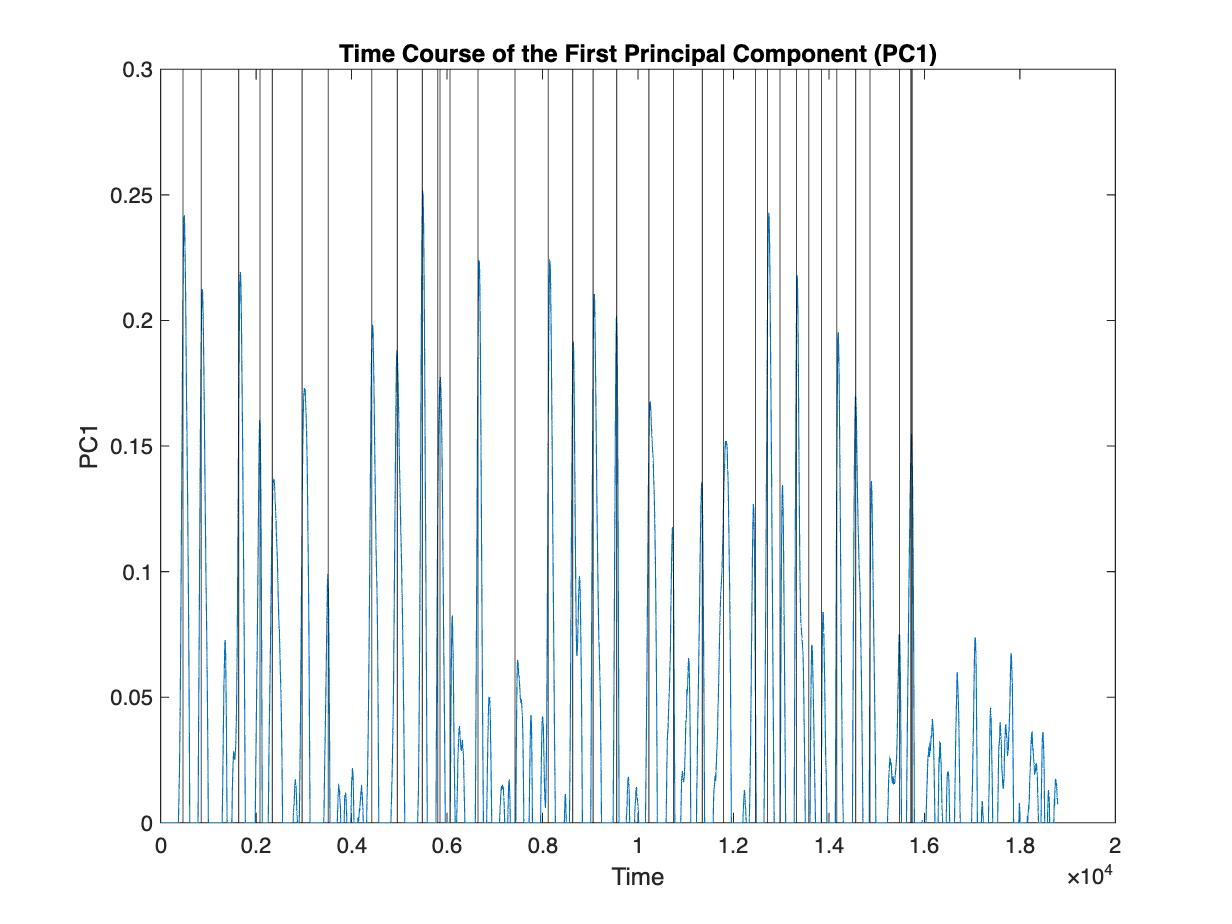

Ftemp=smoothdata(DF,2,"gaussian",200);
% Perform PCA
[coeff, score, ~, ~, explained] = pca(Ftemp');

% Get the PC1 time course
PC1_time_course = diff(score(:, 1));
PC1_time_course(PC1_time_course<0)=0;
%Plot the PC1 time course
plot(PC1_time_course);
title('Time Course of the First Principal Component (PC1)');
xlabel('Time');
ylabel('PC1');
xline(start_indices,LineWidth=0.5,Color='k')


% Identify the 10% of variables with the highest weights in PC1
numVariables = size(DF, 1);
numTopVariables = ceil(0.05 * numVariables);
[~, idx] = sort(abs(coeff(:, 1)), 'descend');
topVariablesIdx = idx(1:numTopVariables);

% Create a new dataset containing only these top variables
dataTop = Ftemp(topVariablesIdx, :);

% Center the new dataset
% dataTopCentered = dataTop - mean(dataTop);

% Calculate the PC1 time course for the new dataset
coeffTop = coeff(topVariablesIdx,1);
PC1_time_course = dataTop' * coeffTop;
PC1_time_course = diff(PC1_time_course);
PC1_time_course (PC1_time_course <0)=0;
% Plot the PC1 time course
plot(PC1_time_course);
title('Time Course of the First Principal Component (PC1) - Top 10% Variables');
xlabel('Time');
ylabel('PC1');

colors = [
    1 0 0;     % Red 
    0 1 0;     % Green
    0 0 1;     % Blue
    1 1 0;     % Yellow
    1 0 1;     % Magenta
    0 1 1;     % Cyan
    0.5 0 0;   % Maroon
    0 0.5 0;   % Olive
    0 0 0.5;   % Navy
    0.5 0.5 0; % Olive Green
    0.5 0 0.5; % Purple
    0 0.5 0.5; % Teal
    0.75 0 0;  % Dark Red
    0 0.75 0;  % Lime Green
    0 0 0.75;  % Dark Blue
    0.75 0.75 0; % Dark Yellow
    0.75 0 0.75; % Dark Magenta
    0 0.75 0.75; % Dark Cyan
];

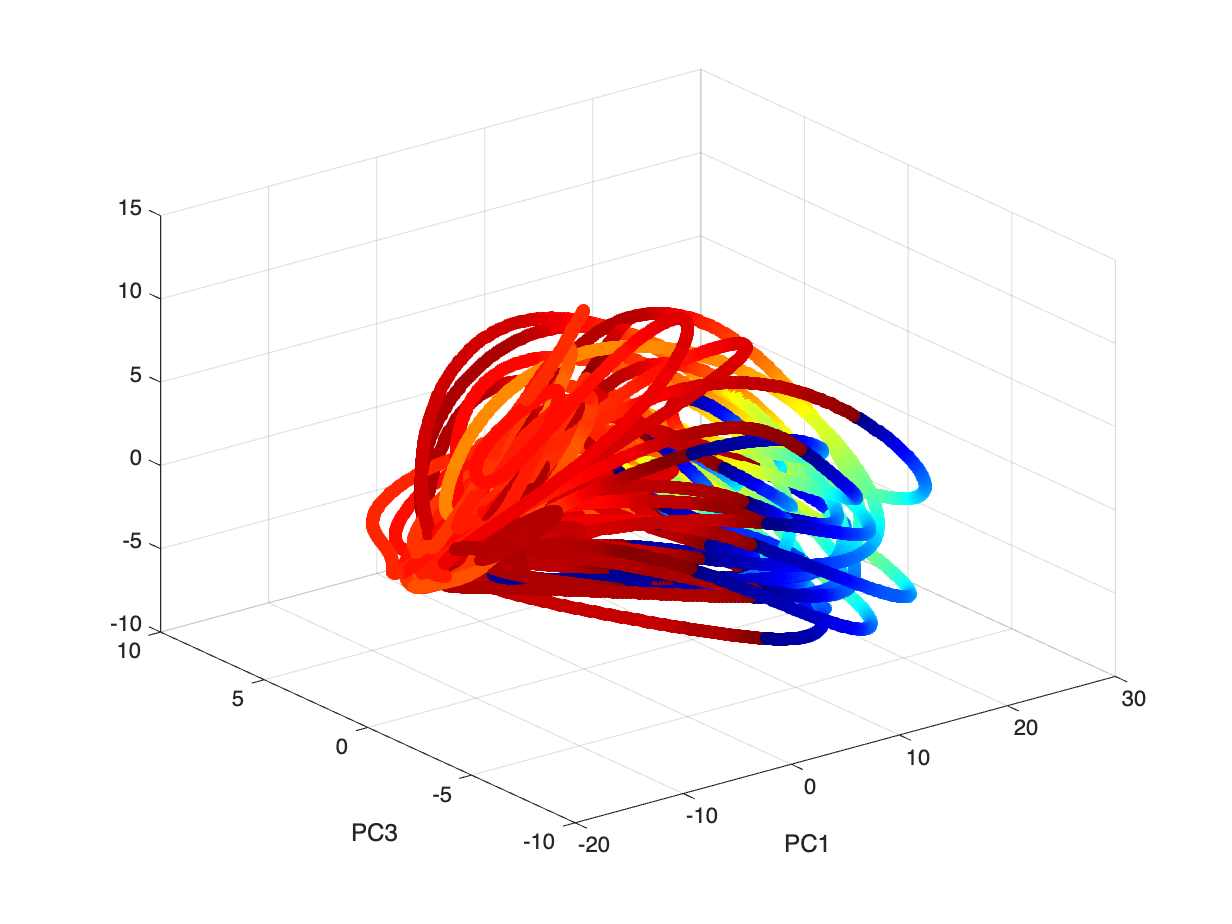


figure
colormap jet
colorbar
debut=1;%start_indices(1);
fin=Nz;% end_indices(35);
couleur=colormap(jet(Nz));

% Générer la colormap
couleur = jet(192);
position_round=ceil(position);

PC1=1;
PC2=2;
PC3=3;

% scatter3(score(debut:fin,PC1),score(debut:fin,PC2),score(debut:fin,PC3),1,'filled','MarkerFaceColor','k');
% scatter3(score(:,PC1),score(:,PC2),score(:,PC3),1,'filled','MarkerFaceColor','k');
scatter3(score(:,PC1),score(:,PC2),score(:,PC3),[],couleur(position_round,:),'filled');
% plot3(score(:,PC1),score(:,PC2),score(:,PC3),'Color',couleur(position_round,:),'LineWidth',2)
% hold on
% for n=1:4:1000
%     scatter3(score(n,PC1),score(n,PC2),score(n,PC3),3,'filled','MarkerFaceColor',couleur(position_round(n),:));
% 
% end
% % scatter3(score(n,PC1),score(n,PC2),score(n,PC3),1,'filled','MarkerFaceColor',couleur(position_round,:));
% hold on
% for n=10:15%numel(start_indices)
%     window=start_indices(n):end_indices(n);
%     scatter3(score(window,PC1),score(window,PC2),score(window,PC3),'filled','MarkerFaceColor',colors(n,:));
% end
xlabel('PC1');
ylabel('PC2');
ylabel('PC3');

hold off

% %PSTH for calcium based on run onset
% window=100;
% PSTH=[];
% for n=1:numel(start_indices)
%     start=start_indices(n);
%     PSTH(:,:,n)=DF(:,start-50:start+200);
% end
% mean_PSTH=mean(PSTH,3);
% figure
% % imagesc(mean_PSTH(idx2,:))
% imagesc(mean_PSTH)
% % imagesc(PSTH(isort1,:,1))
% colormaca ("hot")
% caxis ([0 2])
% 
% set(gcf, 'Position', [10 10 1000 2000]);

%Arnaud/Robin : do order on whole train and use Kendal tau to test on each
%run (maybe spearman would have been better) 
%
%PSTH train
PSTH=[];
train_test_ratio=0.5;
ntrain=round(numel (start_indices)*train_test_ratio);
% list_indices=randi([1,start_indices],1,numel(start_indices))
list_indices=randperm(numel(start_indices));
list_indices_train=list_indices(1:ntrain);

list_indices_test=list_indices(ntrain+1:end);
for n=1:numel (list_indices)
    start=start_indices(n);
    PSTH(:,:,n)=DF(:,start-100:start+200);
end
mean_PSTH_train=mean(PSTH(:,:,list_indices_train),3);
mean_PSTH_test=mean(PSTH(:,:,list_indices_test),3);
mean_PSTH=mean(PSTH,3);
% imagesc(mean_PSTH(idx2,:))
% imagesc(mean_PSTH_train(newidx,:))
figure
imagesc(mean_PSTH_train)
% imagesc(PSTH(isort1,:,1))
colormap ("hot")
caxis ([0 2])
set(gcf, 'Position', [10 10 200 400]);

imagesc(mean_PSTH_test)
% imagesc(PSTH(isort1,:,1))
colormap ("hot")
caxis ([0 2])
set(gcf, 'Position', [10 10 200 400]);


%PSTH for calcium based on run onset
% %window=100;
% speed_PSTH=[];
% %smoothed_speed=smoothdata(speed,2,"gaussian",100);
% for n=1:numel(start_indices)
%     start=start_indices(n);
%     speed_PSTH(:,n)=speed(start-50:start+200);
% end
% mean_speed_PSTH=median(speed_PSTH,2);
% 
% figure
% plot(mean_speed_PSTH)

max_lag = 100;
max_corr_sh_values=[];
max_corr_values=[];
lags_at_max_corr = [];
start_run_binary=zeros(1,size(DF,2));
start_run_binary(1,start_indices)=1;
Window_train=[];
extra_window=0;

for n=list_indices_train
    Window_train= [Window_train start_indices(n)-extra_window:end_indices(n)+extra_window];
end

tic
% 
% test=diff(mean_DF);
% test=diff(speed);

for i = 1:NCell%-1
        % [cross_corr, lags] = xcorr(smoothed_mean_DF, DF(i, :), max_lag,"coeff");
        [cross_corr, lags] = xcorr(start_run_binary(Window_train), DF(i,Window_train), max_lag,"coeff");
        % [cross_corr, lags] = xcorr(start_run_expdecay(Window_train), DF(i,Window_train), max_lag,"coeff");
        % [cross_corr, lags] = xcorr(start_run_binary(Window_train), DF(i,Window_train), max_lag,"coeff");
% [cross_corr, lags] = xcorr(PC1_time_course(:), DF(i,1:end-1), max_lag,"coeff");

        
        % [cross_corr, lags] = xcorr(speed(:), DF(i,:), max_lag,"coeff");
                   
        % Find maximum correlation and corresponding lag and store
        [max_corr_values(i), idx_max_corr] = max(cross_corr);
        lags_at_max_corr(i) = lags(idx_max_corr);
        % max_corr_values(i) = max_corr;
end



% [~,bestcell]=max(max_corr_values)
% % bestcell=67
% lags_at_max_corr(bestcell) 
% 
% % find (lags_at_max_corr==0)
% plot(DF(bestcell,WinActive));hold on ;plot(speed(WinActive));
% % scatter(start_indices, binary_smoothed_speed(start_indices), 'g', 'filled');
% hold off
% 
% max_lag = 150;
% max_corr_sh_values=[];
% max_corr_values=[];
% lags_at_max_corr = [];
% 
% for i = 1:NCell%-1
% 
%         [cross_corr, lags] = xcorr( DF(bestcell, WinActive), DF(i, WinActive), max_lag,"coeff");
%         % Find maximum correlation and corresponding lag and store
%         [max_corr, idx_max_corr] = max(cross_corr);
%         lags_at_max_corr(i) = lags(idx_max_corr);
%         max_corr_values(i) = max_corr;
% end
% %permutation to determine threshold correlation
% % nshuffle=100;
% % tic
% % parfor n=1:nshuffle
% %     idx = randperm(Nt);
%     start_run_binary_sh=start_run_binary(idx);
% 
%     for i = 1:NCell%-1
%             [cross_corr, lags] = xcorr(start_run_binary_sh, DF(i, :), max_lag,"coeff");
%             [max_corr, idx_max_corr] = max(cross_corr);
%             max_corr_sh_values(i,n) = max_corr;
%     end
% end
% toc
% Thr=prctile(max_corr_sh_values,95,'all')

%find significant correlation
Thr = graythresh(max_corr_values)
[~ ,idx1]=find(max_corr_values>Thr & lags_at_max_corr<0);
% [~ ,idx1]=find(lags_at_max_corr<0);
% [~ ,idx1]=find(max_corr_values>0);
%sort by lag

[test , idx2 ]=sort(lags_at_max_corr(idx1),2,'descend');


newidx=idx1(idx2);

% [~ , idx2 ]=sort(lags_at_max_corr,2,'descend');

figure
Ftemp=smoothdata(DF,2,"gaussian",100);
imagesc(Ftemp(newidx,:))
caxis ([0.1 5])
colormap ("hot")
hold on
plot (-speed*10,'Color','k')
ylim([-300 numel(newidx)]) 
hold off


figure
Ftemp=smoothdata(DF,2,"gaussian",100);
% imagesc(Ftemp(DC(xDel),1:3000))
ngraph=round(Nz/3000);
for n=1:ngraph
    subplot(ngraph,1,n)
    imagesc(Ftemp(newidx,3000*(n-1)+1:3000*n))
    % imagesc(Ftemp(isort1,3000*(n-1)+1:3000*n))
    % imagesc(Ftemp(idx2,:))
    colormap ("hot")
    caxis ([0.1 5])
    set(gcf, 'Position', [0 0 1000 300]);
    % xline(start_indices,LineWidth=1,Color='w')
end

% xline(start_indices,LineWidth=1,Color='w')
set(gcf, 'Position', [10 10 800 500]);

% imagesc(mean_PSTH(idx1(idx2),:))
% smoothed_PSTH=smoothdata(mean_PSTH_train,2,"gaussian",10);
smoothed_PSTH=smoothdata(mean_PSTH,2,"gaussian",10);
% imagesc(mean_PSTH(idx2,:))
% imagesc(smoothed_PSTH(idx2,:))
figure
imagesc(smoothed_PSTH(newidx,:))

% imagesc(PSTH(isort1,:,1))
colormap ("hot")
caxis ([0.1 5])
xline(100,'LineWidth',2,'Color','w')
set(gcf, 'Position', [10 10 500 500]);
figure
% imagesc(mean_PSTH(idx1(idx2),:))
smoothed_PSTH1=smoothdata(mean_PSTH_test,2,"gaussian",10);
% imagesc(mean_PSTH(idx2,:))
% imagesc(smoothed_PSTH(idx2,:))
imagesc(smoothed_PSTH1(newidx,:))
% imagesc(PSTH(isort1,:,1))
colormap ("hot")
caxis ([0.1 5])
xline(100,'LineWidth',2,'Color','w')
set(gcf, 'Position', [10 10 500 500]);
% test_spearman=xcorr(newidx,test_idx)

max_lag = 100;
max_corr_values=[];
lags_at_max_corr = [];
Window_test=[];
extra_window=0;

for n=list_indices_test
    Window_test= [Window_test start_indices(n)-extra_window:end_indices(n)+extra_window];
end

for i = 1:NCell%-1

        [cross_corr, lags] = xcorr(start_run_binary(Window_test), DF(i,Window_test), max_lag,"coeff");

        % Find maximum correlation and corresponding lag and store
        [max_corr_values(i), idx_max_corr] = max(cross_corr);
        lags_at_max_corr(i) = lags(idx_max_corr);

end
Thr = graythresh(max_corr_values)
[~ ,idx1]=find(max_corr_values>Thr & lags_at_max_corr<0);
% [~ ,idx1]=find(lags_at_max_corr<0);
% [~ ,idx1]=find(max_corr_values>0);
%sort by lag

[test , idx2 ]=sort(lags_at_max_corr(idx1),2,'descend');


idx_test=idx1(idx2);
figure
% imagesc(mean_PSTH(idx1(idx2),:))
smoothed_PSTH1=smoothdata(mean_PSTH_test,2,"gaussian",10);
% imagesc(mean_PSTH(idx2,:))
% imagesc(smoothed_PSTH(idx2,:))
imagesc(smoothed_PSTH1(idx_test,:))
% imagesc(PSTH(isort1,:,1))
colormap ("hot")
caxis ([0.1 5])
xline(100,'LineWidth',2,'Color','w')
set(gcf, 'Position', [10 10 500 500]);
% test_spearman=corr(newidx',idx_test','Type', 'Spearman')


return

%plot color of cells on sorted raster
% oldisort1=isort1;
isort1=newidx;
figure
Ftemp=smoothdata(DF,2,"gaussian",100);
imagesc(Ftemp(isort1,:))

colormap ("hot")
caxis ([0 2])
i=0;
for n=1:NCell

    if colorcell(isort1(n))==1
        col='red';
    elseif colorcell(isort1(n))==2 
        col='green';
    elseif colorcell(isort1(n))==3 
        col='blue';
    elseif colorcell(isort1(n))==4 
        col='yellow';
        % col='white';
    elseif colorcell(isort1(n))==5 
        col='magenta';
    elseif colorcell(isort1(n))==6 
        col='cyan';
    elseif colorcell(isort1(n))==7 
        col='black';
    elseif colorcell(isort1(n))==8 
        col='black';

    end
        % yline(isort1(n),'LineWidth',1,'Color',col)
        line([-1000 0], [isort1(n) isort1(n)], 'LineWidth', 1 , 'Color', col);
        i=i+1;
end
xlim([-1000 Nz]) 
% namegraph=strcat(['rastermap_run assembly' num2str(ass), '.png']);
% exportgraphics(gcf,[namefull namegraph],'Resolution',300,'BackgroundColor','black')


%plot assembly over sorted raster

for ass=1:numel(assembly)
    %figure('visible','off');
    figure
    Ftemp=smoothdata(DF,2,"gaussian",100);
    % imagesc(Ftemp(idx2,:))
    imagesc(mean_PSTH(newidx,:))
    colormap ("hot")
    title (['Assembly' num2str(ass)])
    caxis ([0 2])
    i=0;
    for n=cell2mat(assembly(ass))
        y=find (n==newidx);

    if colorcell(n)==1
        col='red';
    elseif colorcell(n)==2 
        col='green';
    elseif colorcell(n)==3 
        col='blue';
    elseif colorcell(n)==4 
        col='yellow';
    elseif colorcell(n)==5 
        col='magenta';
    elseif colorcell(n)==6 
        col='cyan';
    elseif colorcell(n)==7 
        col='white';
    elseif colorcell(n)==8 
        col='white';

    end
        yline(y,'LineWidth',1,'Color',col)
        % i=i+1;
        % yline(y,'LineWidth',1,'Color',colors(ass,:))
        if y>200
            i=i+1;
        end


    end
        i/numel(cell2mat(assembly(ass)))*100
    % namegraph=strcat(['rastermap_run assembly' num2str(ass), '.png']);
    % exportgraphics(gcf,[namefull namegraph],'Resolution',300,'BackgroundColor','black')
end

% % quelles cellules actives dans run , en séquence ou correlé  
% i=0;
% Ftemp=smoothdata(DF,2,"gaussian",100);
% for n=isort1(29)'
%     i=i+1;
%     [ampli ,locs ,width_peak]=findpeaks(Ftemp(n,WinActive),'MinPeakProminence',2,'MinPeakWidth',20);%,'MinPeakWidth',10
%     ampli_run{i}=ampli;
%     locs_run{i}=locs;
%     width_peak_run{i}=width_peak;
% 
%     if numel(ampli)>10
%         run(i)=1;
%     else
%         run(i)=0;
%     end
% end
% bar(run)

% isort1=oldisort1;
% distance intra-assemblée

for ass=1:numel(assembly)
    isort1_ass=[];
    for n=cell2mat(assembly(ass))

        % y=find (n==isort1);
        y=find (n==newidx);
        isort1_ass=[isort1_ass  y];
        
    end
    pairwise_distance=pdist(newidx');
    mean_pairwise_distance(ass)=mean(pairwise_distance)/NCell;
    % figure
    % histogram(pairwise_distance)
    % title (['assembly ' num2str(ass)])

end
mean_pairwise_distance
%mean_pairwise_distance



%representation with cumulative distance
sampling_rate=10;
deltaTime = 1/sampling_rate; % Time interval between measurements, adjust as necessary

% Convert speed to distance for each interval
distanceMatrix = speed * deltaTime; % If deltaTime is 1, this line can be omitted

% Calculate cumulative distance
cumulativeDistance = cumsum(distanceMatrix, 1); % Assuming time is along the second dimension (columns)
epsilon = 1e-6; % Small value to adjust duplicates
for i = 2:length(cumulativeDistance)
    while ismember(cumulativeDistance(i), cumulativeDistance(1:i-1))
        cumulativeDistance(i) = cumulativeDistance(i) + epsilon;
    end
end
% Desired distances for interpolation
desiredDistances = linspace(min(cumulativeDistance(:)), max(cumulativeDistance(:)), Nz);

% Interpolating neuronal activity to these distances
% Assuming neuronal activity is sampled in such a way that each column corresponds to the measurements in cumulativeDistance
% interpolatedActivity = interp1(desiredDistances, Tr1b(1,:),'linear');
for cellIdx = 1:size(DF, 1)
    % interpolatedActivity(cellIdx, :) = interp1(cumulativeDistance, Tr1b(cellIdx, :), desiredDistances, 'linear');
    interpolatedActivity(cellIdx, :) = interp1(cumulativeDistance, DF(cellIdx, :), desiredDistances, 'linear');

end

% Now you can plot, here's an example of plotting the activity of the first cell
% figure
% plot(desiredDistances, interpolatedActivity(1, :));
% xlabel('Cumulative Distance');
% ylabel('Neuronal Activity');
%resample interpolatedActivity
[P, Q] = rat(max(desiredDistances)/Nz); % Compute rational approximation for the resampling factor
resamp_interpolatedActivity = resample(interpolatedActivity', P, Q)';



Ftemp=smoothdata(resamp_interpolatedActivity,2,"gaussian",100);
% Ftemp=smoothdata(Ftemp,1,"gaussian",10);
imagesc(Ftemp(newidx,:))
colormap ("hot")
hold on
% plot (-cumulativeDistance/10)
% plot(-interpolatedActivity(124, :)*100-10);
% plot(-interpolatedActivity(427, :)*100-110);
hold off
% plot (-binary_signal*20)
% hold off

caxis ([0 2])
ylim([0 NCell]) 

%mean 10% isort1

meantrace=mean(resamp_interpolatedActivity(isort1(1:200),:),1);


figure
plot(interpolatedActivity(1, :));
hold on
plot(Tr1b(1, :));


% caxis ([1 1.5])
% axis off
% axis image
 
% namegraph=strcat(PathSave ,['allcells' , '.png']);
% 
% exportgraphics(gcf,namegraph,'Resolution',300,'BackgroundColor','black')

for ass=1:numel(assembly)
    %figure('visible','off');
    figure
    Ftemp=smoothdata(DF,2,"gaussian",100);
    % test=smoothdata(test,1,"gaussian",10);
    % newF=Ftemp(isort1,:);
    % imagesc(Ftemp(isort1,:))
    imagesc(Ftemp(newidx,:))
    % imagesc(Race(isort1,:))
    colormap ("hot")
    caxis ([0 6])

    for n=cell2mat(assembly(ass))
        y=find (n==newidx);
        % text(0, y, '.', 'FontSize', 20,'Color',colors(ass,:))
        yline(y,'LineWidth',1,'Color',colors(ass,:))
    end
    % namegraph=strcat(['rastermap_run assembly' num2str(ass), '.png']);
    % 
    % exportgraphics(gcf,[namefull namegraph],'Resolution',300,'BackgroundColor','black')
end
% num_cell_assembly=cell2mat(assembly(1));
% text(xPosition, yHauteur, '*', 'FontSize', 14)
return


%overlap with assembly
for n=1:numel (assembly)
        intersection{n}=intersect(isort1(1:NCell),cell2mat(assembly(n)));
        inter(n)=numel(intersection{n})/numel(cell2mat(assembly(n)));
end
figure
for n=1:numel (assembly)
    
    bar (inter)
    % hold on
    % title(['intersection cluster ortho' num2str(n)])
end
% hold off




%calculate cross_correlation with start of run
max_lag=200;
start_run_binary=zeros(1,size(DF,2));
start_run_binary(1,start_indices)=1;
Frun=zeros(NCell,size(DF,2));
Frun(:,WinActive)=DF(:,WinActive);
% smoothed_F=smoothdata(Tr1b,2,"gaussian",100);


for n = 1:NCell
    [cross_corr, lags] = xcorr(start_run_binary, Frun(n,:), max_lag,"coeff");
    [max_corr, idx_max_corr] = max(cross_corr);
    lag_at_max_corr = lags(idx_max_corr);
    max_corr_values(n) = max_corr;
    lags_at_max_corr(n) = lag_at_max_corr;
end

[a b]=sort(lags_at_max_corr);
figure
imagesc(mean_PSTH(b,:))
colormap ("hot")
caxis ([0.1 3])
hold on
% xline (start_indices,Color='g',LineWidth=1)
% xline (end_indices,Color='w',LineWidth=1)
hold off


% calcul correlation pendant run en fonction distance entre cellules
max_lag = 100;
lag=[-100:-1 1:100];
DF=double(F(iscell(:,1)>0,:));
NCell=size(DF,1);
% Initialize arrays to store results
max_corr_values = zeros(NCell, NCell);
lags_at_max_corr = zeros(NCell, NCell);
distance_ij = zeros(NCell, NCell);
DF=normalize(DF,2,'zscore');
DF=DF(isort1,:);
tic
for i = 1:NCell-1
    for j = i+1:NCell
        % Calculate cross-correlation
        [cross_corr, lags] = xcorr(DF(i, WinActive), DF(j, WinActive), max_lag,"coeff");
             
        
        % Find maximum correlation and corresponding lag
        [max_corr, idx_max_corr] = max(cross_corr);
        lag_at_max_corr = lags(idx_max_corr);
        distance_ij(i,j) = sqrt((gcamp_centroid(i,1)-gcamp_centroid(j,1))^2+ (gcamp_centroid(i,2)-gcamp_centroid(j,2))^2);
        distance_ij(i,j)
        % Store results
        max_corr_values(i,j) = max_corr;
        lags_at_max_corr(i,j) = lag_at_max_corr;
    end
    %i
end

figure
scatter(max_corr_values,distance_ij)

% Paramètres de la fonction
mu = 20; % Moyenne (position du pic)
sigma = 50; % Écart-type (contrôle la largeur du pic)
decay_tau = 5000; % Temps caractéristique pour la décroissance (plus grand = décroissance plus lente)
rise_tau = 10;
peak_height = 1; % Hauteur du pic

% Créer un vecteur de valeurs x
x = linspace(-500, 500, 1000); % Par exemple, de -500 à 500 avec 1000 points

% Calculer les valeurs de la fonction
y_gaussian = peak_height * exp(-(x - mu).^2 / (2 * sigma^2)); % Fonction gaussienne pour la montée
% y_rise= peak_height * (1 - exp(-x / rise_tau));
y_decay = peak_height * exp(-x / decay_tau); % Fonction exponentielle pour la décroissance

% Combinaison de la montée et de la décroissance
y_combined = y_gaussian .* y_decay ;

% Tracer la fonction combinée
plot(x, y_combined);
% plot(x, y_decay);
xlabel('x');
ylabel('Hauteur');